# A first look at the data

## Introduction

In this section we will set the paths and load the data. We will then explain the data structure and do a few sanity checks. Finally follow some examples for how to perform simples plots of the raw data.

## **Data recording**

The Elekta/MEGIN  data are stored in the FIFF-format. This is one binary data field that  contains the raw MEG data as well as all the relevant parameters.

The recording was done at 1000Hz sampling rate, included combined MEG recording and lasted approx. 40 min. The Elekta/MEGIN system allows for max 1.86GB for each raw MEG FIFF file. Once the recording exceeds  1.86GB a new FIFF file is created. The recorded data size of the tutorial dataset is over 3.7GB. Hence the recording contains two  datafiles which correspond to the first and the second part (in time) of the recording. 

*training_raw-1.fif*

*training_raw-2.fif*

## **Loading the data**

As a first step, we set the path to the data. Note that this will dependent on where you have stored the dataset. Afterwards, we set the  file names.

data_path = 'C:\Users\Tamas\Documents\';%C:\Users\JensenO\Dropbox\FLUX\Development\dataRaw\';
file_name = ['training_raw-1.fif';'training_raw-2.fif'];

Make sure FieldTrip is installed and path is set, see [https://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/](https://www.fieldtriptoolbox.org/faq/should_i_add_fieldtrip_with_all_subdirectories_to_my_matlab_path/) . 

Once the filedtrip path is set run ft_defaults to add some variables and further paths for fieldtrip to run.  

ft_defaults

## **Reading the header**

Take the first dataset 'training_raw-1.fif'. Call  ft_read_header.m to get some relevant information about the fif file.  

cfg=[];
cfg.dataset  = [data_path, file_name(1,:)];
hdr  = ft_read_header(cfg.dataset);

	Read a total of 8 projection items:
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_raw-1.fif ...
	Read a total of 8 projection items:
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
Opening raw data file C:\Users\Tamas\Documents\training_raw-1.fif...
	Read a total of 8 project

To explore the header run the line below.

hdr

hdr = struct with fields:
          label: {343×1 cell}
         nChans: 343
             Fs: 1000
           grad: [1×1 struct]
       nSamples: 1457000
    nSamplesPre: 0
        nTrials: 1
           orig: [1×1 struct]
       chantype: {343×1 cell}
       chanunit: {343×1 cell}


The sampling frequency was 1000 Hz (Fs) and the total number of recorded samples was 1 457 000 in 343 channels . To get some additional information explore the orig field of the hdr structure.

hdr.orig

ans = struct with fields:
         file_id: [1×1 struct]
         meas_id: [1×1 struct]
       meas_date: [2×1 int32]
           nchan: 343
           sfreq: 1000
        highpass: 0.1000
         lowpass: 330
             chs: [1×343 struct]
        ch_names: {1×343 cell}
      dev_head_t: [1×1 struct]
      ctf_head_t: []
       dev_ctf_t: []
             dig: [1×403 struct]
            bads: []
           projs: [1×8 struct]
           comps: [0×0 struct]
        acq_pars: 'ACQactiveGround 1↵ACQch.BIO001.gain 2000↵ACQch.BIO001.highpass 0.1 ↵ACQch.BIO001.label BIO001↵ACQch.BIO001.lowpass 330 ↵ACQch.BIO001.on 1↵ACQch.BIO001.type 102↵ACQch.BIO002.gain 2000↵ACQch.BIO002.highpass 0.1 ↵ACQch.BIO002.label BIO002↵ACQch.BIO002.lowpass 330 ↵ACQch.BIO002.on 1↵ACQch.BIO002.type 102↵ACQch.BIO003.gain 2000↵ACQch.BIO003.highpass 0.1 ↵ACQch.BIO003.label BIO003↵ACQch.BIO003.lowpass 330 ↵ACQch.BIO003.on 1↵ACQch.BIO003.type 102↵ACQch.BIO004.gain 2000↵ACQch.BIO004.highpass 0.1 ↵ACQch.BIO004.label BIO00

This set of information show some further important parameters of the dataset. For  instance, the data were lowpass filtered at 330.0 Hz (*lowpass*) and highpass filtered at 0.1 Hz (*highpass*) prior to the digital sampling.

### **Question 1**

What is the purpose of the 330 Hz lowpas-filter (hint: see Analog Filters for Data Conversion, Chapter 3; Smith et al., 1999)

### Question 2 

What is the purpose of 0.1 Hz highpass-filter?

## **The channels**

From this structure we can infer that nChans = 343 have been  recorded. There are 306 MEG sensors which are listed in the label field  starting with row 15 up to row 320. These are organised in triplets of  two planar gradiometers on magnetometers. Inspect the first three by writing **hdr.label(15:17)** in the command window.

MEG0111 is a magnetometer and MEG0113 and MEG0112 are two orthogonal planar gradiometers; all on the same chip (see hdr.chantype).

The variable hdr.grad contains various information about the magnetometers and gradiometers. For instance hdr.grad.chanpos contains the location of the MEG in 3D coordinates. Plot those to see the helmet geometry: 

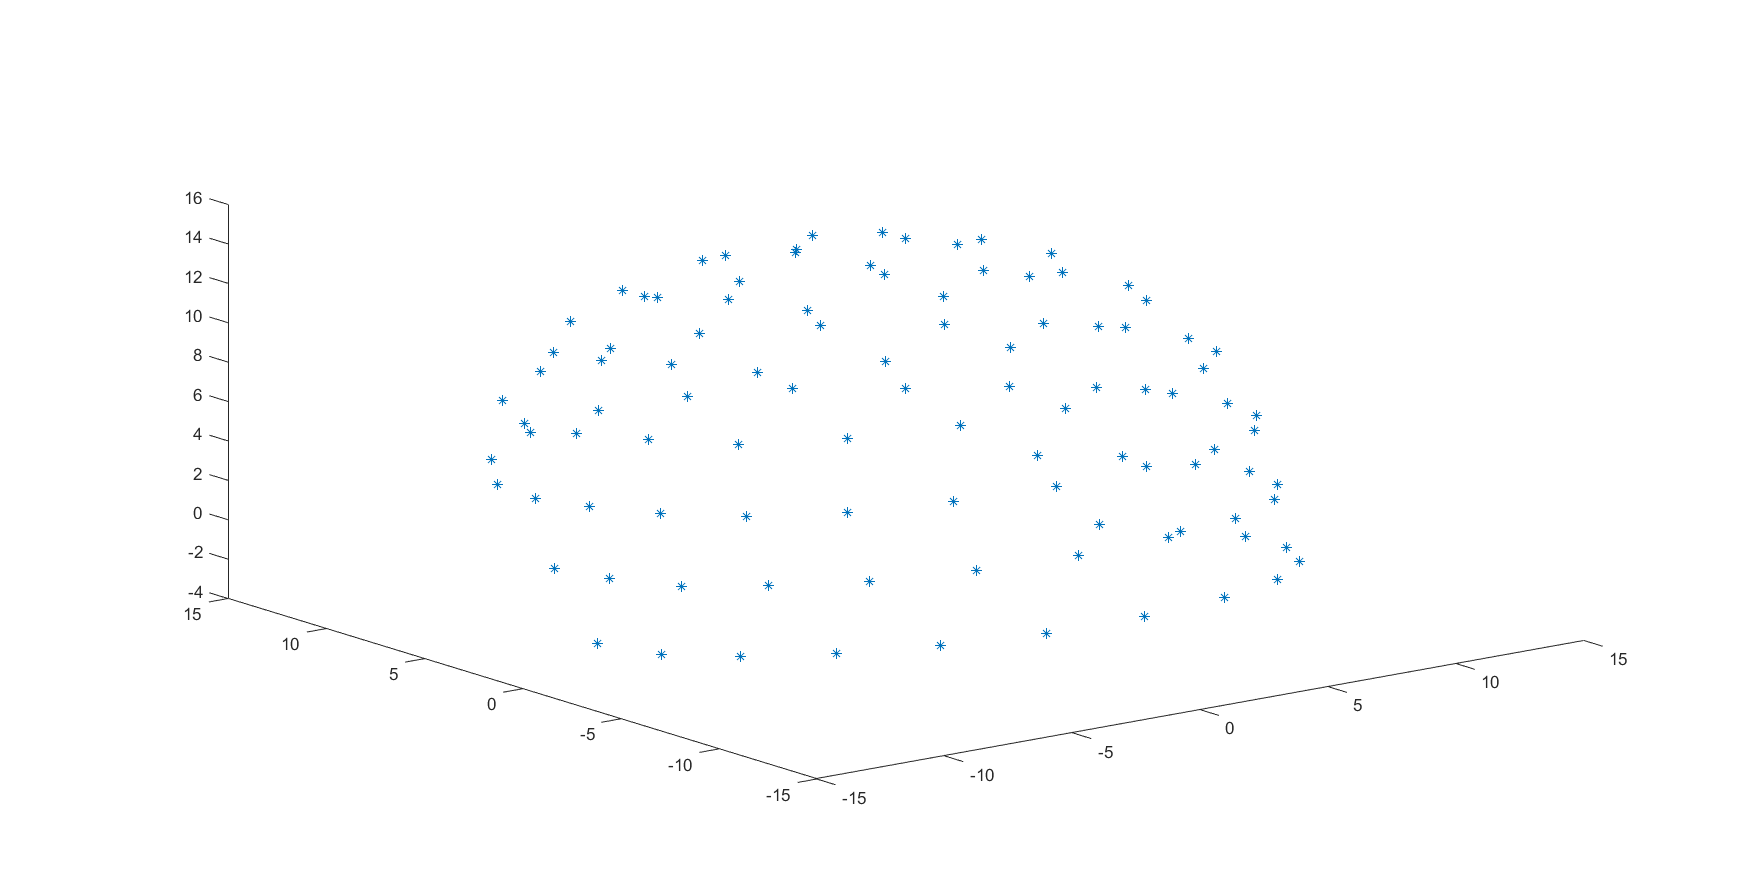

plot3(hdr.grad.chanpos(:,1),hdr.grad.chanpos(:,2),hdr.grad.chanpos(:,3),'*')

### **Question 3**

The variable hdr.grad.coilpos has diminution [510x3 double]. What might the 510 positions refer to?  

The MEG sensors are preceded by the vEOG, hEOG and cardiac  electrode channels (BIO001,BIO002,BIO003, respectively) and headposition monitoring channels in the channel list (IAS channels). The MEG channels are directly followed by 3 eyetracker channels (MISC001,MISC002,  MISC003)   The rest of the channels (324 to  343) are the stimulus trigger channels amongst which channel 340 is of particular importance. Write  **hdr.label{340}** in the command window.

This channel encodes the stimulus channel containing the trigger  information. This will be important when segmenting the raw data into  trials. 

## **Reading and plotting channels**

We will plot a few channels to get a feel for the data. The first step is to read the raw data:  

data_exp = ft_read_data(cfg.dataset);

	Read a total of 8 projection items:
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
	306 MEG channel locations transformed
Reading C:\Users\Tamas\Documents\training_raw-1.fif ...
	Read a total of 8 projection items:
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
		generated with autossp-1.2.0 (1 x 306) idle
Opening raw data file C:\Users\Tamas\Documents\training_raw-1.fif...
	Read a total of 8 project

The function returns a matrix of the raw data ('data_exp'): 

size(data_exp)

ans =          343     1457000


To plot 2 s of the data (13 to 15 sec) of the first triplet write 

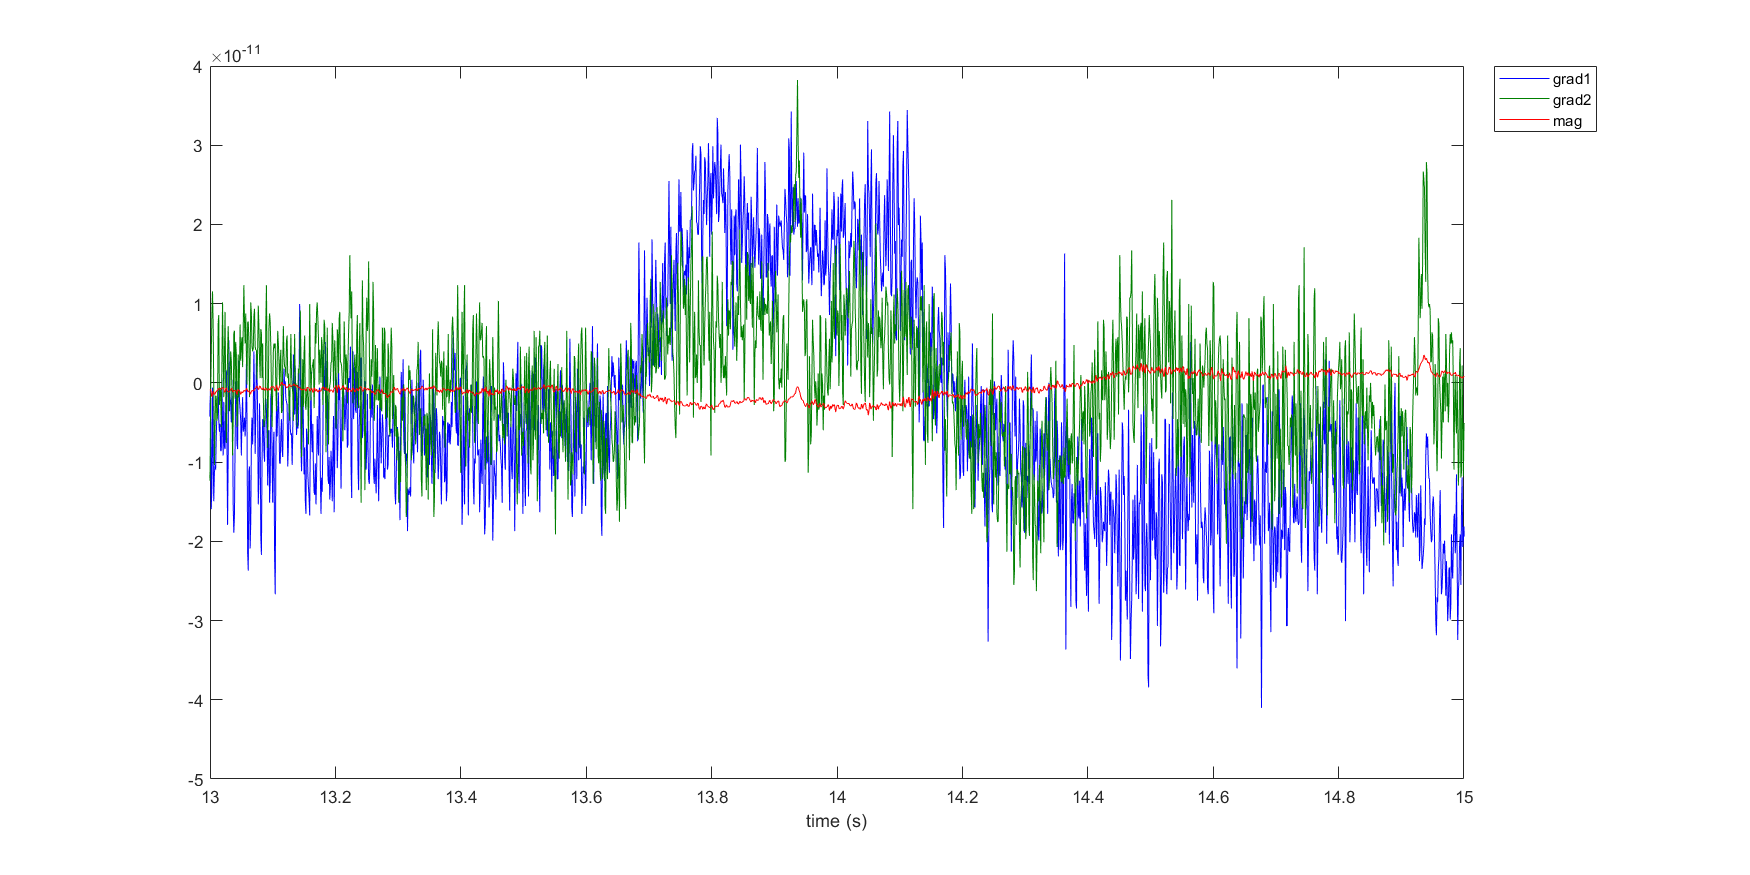

plot((1:length(data_exp))/1000,data_exp(16,:),'b')
hold on
plot((1:length(data_exp))/1000,data_exp(17,:),'color',[0 0.5 0])
plot((1:length(data_exp))/1000,data_exp(15,:),'r')
hold off 
legend('grad1','grad2','mag')
xlabel('time (s)')
xlim([13 15])

### **Question 4**

Why is the scale of the magnetometer (mag) apparently smaller than the signal of the gradiometers (grad1 and grad2)? 

To plot stimulus channel in which the triggers are recorded write: 

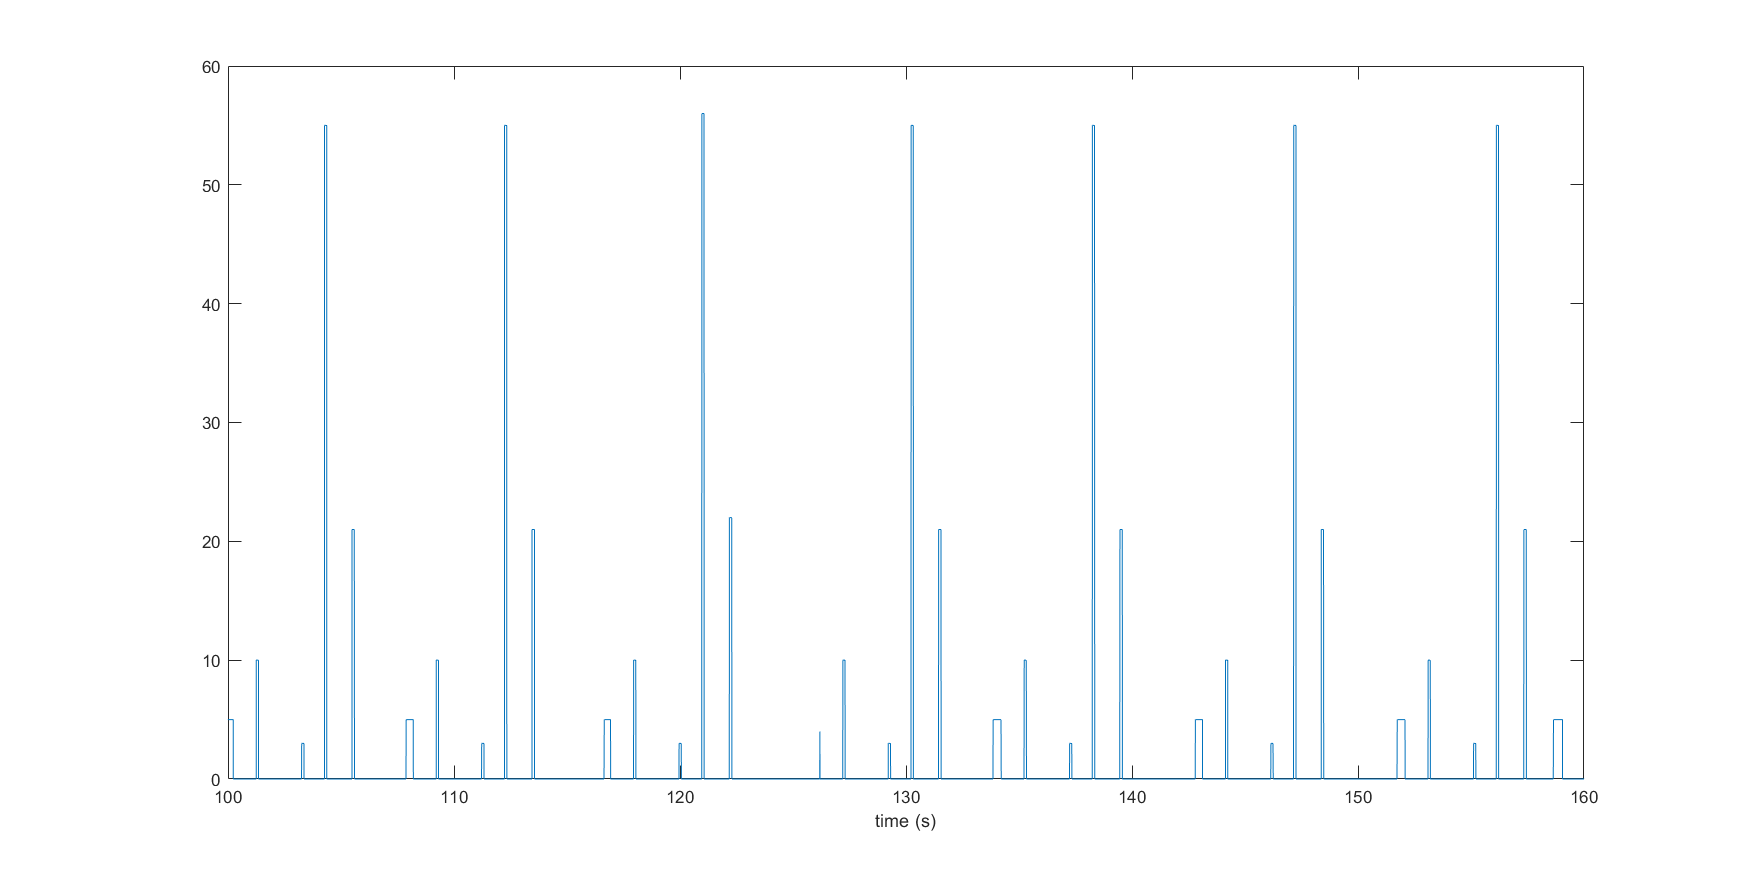

plot((1:length(data_exp))/1000,data_exp(340,:))
xlabel('time (s)')
xlim([100 160])
ylim([0 60])

These triggers indicate the on- and offset of each trials. 

### **Question 5**

Plot a part of the vertical EOG containing an eyeblink. Describe the eyeblink in terms of magnitude and durations. 

## **Preregistration and publications**

Preregistration: report the sampling frequency and the properties of  the anti-aliasing lowpass filter. Also report the peripheral data to be  recorded (e.g. the EOG and ECG)  

Publication, example: 

`"The ongoing MEG data were recored using the TRIUXTM`` system from Elekta/MEGIN. This system has 102 magnetometers and 204 planer gradiometers. These are placed a 306 location each having one magnetometers and a set of two orthogonal gradiometers. The horizontal and vertical EEG were acquired together with the MEG data. The data were sampled at 1000 Hz and stored for offline analysis. Prior to sampling a lowpass filter at ~330 Hz was applied."`

## References

Smith, W.S. (1997) The Scientist  and Engineer's Guide to Digital Signal Processing. California Technical  Publishing. ISBN 0-9660176-3-3. [Online version](http://www.dspguide.com/)